# ED_LSTM_DMPC_PLF_Standard_WLTC

clc;clear;close all;
addpath('./Objfunct_constraint')
addpath('./Data_Standard Driving Cycles')
load PlatoonParameter.mat          % 队列车辆的参数
load('Standard_WLTC.mat')          % 车速

## 运行参数

### 运行步数、时间、步长

Tim_step = 1;                            % 运行步长s
% Time_sim = numel(speed_prediction1);     % 运行时间s
Time_sim = numel(speed_vector);     % 运行时间s
Num_step = Time_sim / Tim_step;          % 运行总步数

### 车辆状态

Postion  = zeros(Num_step,Num_veh);     % 每辆车位置;
Velocity = zeros(Num_step,Num_veh);     % 每辆车速度;
Torque   = zeros(Num_step,Num_veh);     % 每辆车制动和驱动转矩;
Acc      = zeros(Num_step,Num_veh);     % 加速度 
U        = zeros(Num_step,Num_veh);     % 每辆车所需制动和驱动转矩;
Cost     = zeros(Num_step,Num_veh);     % 代价函数
Exitflg  = zeros(Num_step,Num_veh);     % 退出标志

### 领航车

d  = 20;                                % 期望的跟车误差
v0 = zeros(Num_step,1);                 % 车速
x0 = zeros(Num_step,1);                 % 位置

## DMPC参数

% DMPC 加权矩阵
% Fi：通信稳定性；Gi：邻域车辆状态跟随；Qi：领航车状态跟随加权矩阵；Ri：加减速
% F1 = 10*eye(2); G1 = 0;          Q1 = 10*eye(2); R1 = 1;     
% F2 = 10*eye(2); G2 = 10/2*eye(2);Q2 = 10*eye(2); R2 = 1;      
% F3 = 10*eye(2); G3 = 10/2*eye(2);Q3 = 10*eye(2); R3 = 1;     
% F4 = 10*eye(2); G4 = 10/2*eye(2);Q4 = 10*eye(2); R4 = 1;    0.6
% F5 = 10*eye(2); G5 = 10/2*eye(2);Q5 = 10*eye(2); R5 = 1;   

F1 = 8*eye(2); G1 = 0;          Q1 = 10*eye(2); R1 = 10;     
F2 = 8*eye(2); G2 = 10/2*eye(2);Q2 = 10*eye(2); R2 = 10;      
F3 = 8*eye(2); G3 = 10/2*eye(2);Q3 = 10*eye(2); R3 = 10;     
F4 = 8*eye(2); G4 = 10/2*eye(2);Q4 = 10*eye(2); R4 = 10;    
F5 = 8*eye(2); G5 = 10/2*eye(2);Q5 = 10*eye(2); R5 = 10;  

% 分布式模型预测控制状态假设
Np = 5;                         % 预测步长
Pa = zeros(Np,Num_veh);         % 每辆车位置假设;
Va = zeros(Np,Num_veh);         % 每辆车速度假设;
ua = zeros(Np,Num_veh);         % 每辆车制动或跟踪转矩假设，控制输入；
Pa_next = zeros(Np+1,Num_veh);  % 假设每辆车在下一个时间步长的位置;
Va_next = zeros(Np+1,Num_veh);  % 假设每辆车在下一个时间步长的速度;
ua_next = zeros(Np+1,Num_veh);  % 假设每辆车在下一个时间步长的制动或驱动转矩，控制输入；

% 创建options优化结构体：
% Display：显示级别，'off' 或 'none' ：不显示输出；TolFun：函数值的终止容差；MaxIter：最大迭代次数；
% RelLineSrchBnd：线搜索步长的相对边界；
% RelLineSrchBndDuration：所指定的边界应处于活动状态的迭代次数。
tol_opt = 1e-5;
options = optimset('Display','off','TolFun', tol_opt, 'MaxIter', 2000,...
                'LargeScale', 'off', 'RelLineSrchBnd', [], 'RelLineSrchBndDuration', 1);

% 终端状态 
Xend = zeros(Num_step,Num_veh); 
Vend = zeros(Num_step,Num_veh);

## 车速与位置规划

% 领航车的车速与位置
v0(1) = 0;                              % 初始车速
x0(1) = 0;                              % 初始车速
for i = 2:Num_step
    % v0(i) = speed_prediction1(i);       % 车速更新
    v0(i) = speed_vector(i);       % 车速更新
    x0(i) = x0(i-1)+v0(i)*Tim_step;     % 位置更新
end

% 初始分布 无误差
for i = 1:Num_veh
    Velocity(1,i) = 0;                          % 每辆车初始速度
    Postion(1,i) = x0(1)-i*d;                   % 每辆车初始位置
    Torque(1,i) = (Mass(i)*g*f + Ca(i)*Velocity(1,i)^2)*R(i)/Eta;  % 每辆车初始转矩
end

% 初始化第一次计算的假设状态:匀速
for i = 1:Num_veh
    ua(:,i) = Torque(1,i);      % 控制输入：制动或驱动转矩
    Pa(1,i) = Postion(1,i);     % 假设的第一个点  为文章中的 k=0处，为当前车辆的状态；
    Va(1,i) = Velocity(1,i);    % 车速
    Ta(1,i) = Torque(1,i);      % 转矩
    for j = 1:Np
        % 车辆动力学方程
        % 输入：控制输入(制动、驱动转矩)，时间步长0.1s，预测位置，预测车速，当前转矩(制动、驱动)，车重，车轮半径，重力加速度，摩擦系数，传动效率，风阻系数，时滞常数
        % 输出：下一步位置，下一步车速，下一步转矩
        [Pa(j+1,i),Va(j+1,i),Ta(j+1,i)] = VehicleDynamic(ua(j,i),Tim_step,Pa(j,i),Va(j,i),Ta(j,i),Mass(i),R(i),g,f,Eta,Ca(i),Tao(i));
    end    
end

### 车速与位置

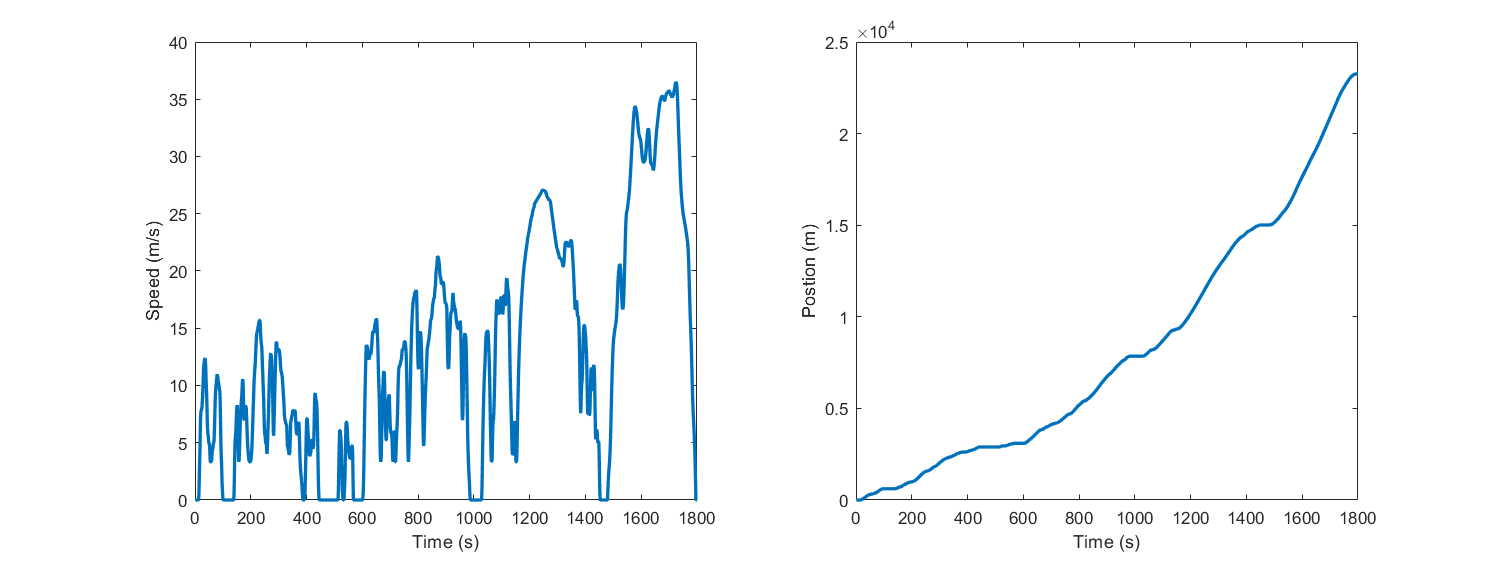

figure;            xlim([0 Num_step]);
subplot(1,2,1);    plot(v0,'linewidth',2);
xlabel('Time (s)');ylabel('Speed (m/s)');
subplot(1,2,2);    plot(x0,'linewidth',2);
xlabel('Time (s)');ylabel('Postion (m)');
set(gcf,'Position',[250 500 1200 450]);

## 循环仿真

tic
for i = 2:Num_step - Np
    % 每50步输出一次
    if rem(i,50) == 0
        fprintf('\n Steps i= %d\n',i)
    end

## 车1

    Vehicle_Type = [Mass(1),R(1),g,f,Eta,Ca(1),Tao(1)];                 % the vehicle parameters ： Mass,R,g,f,Eta,Ca(i),Tao, 
    X0 = [Postion(i-1,1),Velocity(i-1,1),Torque(i-1,1)];                % the vehicle variable in the last time
    Pd = x0(i-1:i+Np-1) - d;  Vd = v0(i-1:i+Np-1);                      % 共Np+1个点，注意下角标，i-1 代表上一时刻的状态， i代表当前需要优化求解的状态
    Xdes = [Pd,Vd];  % Udes = Td;                                       % 第一辆车的期望行为
    Xa = [Pa(:,1),Va(:,1)];                                             % 自己预期的行为，传递给下一辆车
    Xnba = zeros(Np+1,2);                                               % 1：为上一时刻的状态
   
    u0 = ua(:,1);   % 起始搜索点    
    A = [];b = []; Aeq = []; beq = [];                                       % 没有线性约束
    lb = Torquebound(1,1)*ones(Np,1); ub = Torquebound(1,2)*ones(Np,1);      % 控制量上下界              
    Pnp = Pd(end,1); Vnp = Vd(end,1);   % 终端约束
    Xend(i,1) = Pnp; Vend(i,1) = Vnp; Tnp = (Ca(1)*Vnp.^2 + Mass(1)*g*f)/Eta*R(1);
    % MPC 优化求解
    [u, Cost(i,1), Exitflg(i,1), output] = fmincon(@(u) Costfunction2( Np, Tim_step, X0 ,u, Vehicle_Type,Q1,Xdes,R1,F1,Xa,G1,Xnba), ...
        u0, A, b, Aeq, beq, lb, ub, @(u) Nonlinearconstraints(Np, Tim_step, X0, u, Vehicle_Type,Pnp,Vnp,Tnp),options); 
    
    % 车辆往前走一步
    U(i,1) = u(1);
    [Postion(i,1),Velocity(i,1),Torque(i,1)] = VehicleDynamic(U(i,1),Tim_step,Postion(i-1,1),Velocity(i-1,1),Torque(i-1,1),Mass(1),R(1),g,f,Eta,Ca(1),Tao(1));
    
    % 这个地方需要注意,下一阶段的assumed state, 在t+1时刻预测Np自身的状态
    Temp = zeros(Np+1,3);
    Temp(1,:) = [Postion(i,1),Velocity(i,1),Torque(i,1)];   
    ua(1:Np-1,1) = u(2:Np);
    for j = 1:Np-1
        [Temp(j+1,1),Temp(j+1,2),Temp(j+1,3)] = VehicleDynamic(ua(j,1),Tim_step,Temp(j,1),Temp(j,2),Temp(j,3),Mass(1),R(1),g,f,Eta,Ca(1),Tao(1));
    end    
    ua(Np,1) = (Ca(1)*Temp(Np,2).^2 + Mass(1)*g*f)/Eta*R(1);
    [Temp(Np+1,1),Temp(Np+1,2),Temp(Np+1,3)] = VehicleDynamic(ua(Np,1),Tim_step,Temp(Np,1),Temp(Np,2),Temp(Np,3),Mass(1),R(1),g,f,Eta,Ca(1),Tao(1));
    Pa_next(:,1) = Temp(:,1);
    Va_next(:,1) = Temp(:,2);

## 车2

    Vehicle_Type = [Mass(2),R(2),g,f,Eta,Ca(2),Tao(2)];                 % the vehicle parameters ： Mass,R,g,f,Eta,Ca(i),Tao, 
    X0 = [Postion(i-1,2),Velocity(i-1,2),Torque(i-1,2)];                % the vehicle variable in the last time
    Pd = x0(i-1:i+Np-1) - 2*d;  Vd = v0(i-1:i+Np-1);                      % 共Np+1个点，注意下角标，i-1 代表上一时刻的状态， i代表当前需要优化求解的状态
    Xdes = [Pd,Vd];  % Udes = Td;                                       % 第一辆车的期望行为
    Xa = [Pa(:,2),Va(:,2)];                                             % 自己预期的行为，传递给下一辆车
    Xnfa = [Pa(:,1) - d, Va(:,1)];                                               % 1：为上一时刻的状态
   
    u0 = ua(:,2);   % 起始搜索点    
    A = [];b = []; Aeq = []; beq = [];                                       % 没有线性约束
    lb = Torquebound(2,1)*ones(Np,1); ub = Torquebound(2,2)*ones(Np,1);      % 控制量上下界              
    Pnp = (Xnfa(end,1)+Pd(end))/2; Vnp = (Xnfa(end,2)+Vd(end))/2;   % 终端约束
    Xend(i,2) = Pnp; Vend(i,2) = Vnp; Tnp = (Ca(2)*Vnp.^2 + Mass(2)*g*f)/Eta*R(2);
    % MPC 优化求解
    [u, Cost(i,2), Exitflg(i,2), output] = fmincon(@(u) Costfunction2( Np, Tim_step, X0 ,u, Vehicle_Type,Q2,Xdes,R2,F2,Xa,G2,Xnfa), ...
        u0, A, b, Aeq, beq, lb, ub, @(u) Nonlinearconstraints(Np, Tim_step, X0, u, Vehicle_Type,Pnp,Vnp,Tnp),options); 
    
    % 车辆往前走一步
    U(i,2) = u(1);
    [Postion(i,2),Velocity(i,2),Torque(i,2)] = VehicleDynamic(U(i,2),Tim_step,Postion(i-1,2),Velocity(i-1,2),Torque(i-1,2),Mass(2),R(2),g,f,Eta,Ca(2),Tao(2));
    
    % 这个地方需要注意,下一阶段的assumed state, 在t+1时刻预测Np自身的状态
    Temp = zeros(Np+1,3);
    Temp(1,:) = [Postion(i,2),Velocity(i,2),Torque(i,2)]; 
    ua(1:Np-1,2) = u(2:Np);
    for j = 1:Np-1
        [Temp(j+1,1),Temp(j+1,2),Temp(j+1,3)] = VehicleDynamic(ua(j,2),Tim_step,Temp(j,1),Temp(j,2),Temp(j,3),Mass(2),R(2),g,f,Eta,Ca(2),Tao(2));
    end    
    
    ua(Np,2) = (Ca(2)*Temp(Np,2).^2 + Mass(2)*g*f)/Eta*R(2);
    [Temp(Np+1,1),Temp(Np+1,2),Temp(Np+1,3)] = VehicleDynamic(ua(Np,2),Tim_step,Temp(Np,1),Temp(Np,2),Temp(Np,3),Mass(2),R(2),g,f,Eta,Ca(2),Tao(2));
    Pa_next(:,2) = Temp(:,1);
    Va_next(:,2) = Temp(:,2);

## 车3

    Vehicle_Type = [Mass(3),R(3),g,f,Eta,Ca(3),Tao(3)];                 % the vehicle parameters ： Mass,R,g,f,Eta,Ca(i),Tao, 
    X0 = [Postion(i-1,3),Velocity(i-1,3),Torque(i-1,3)];                % the vehicle variable in the last time
    Pd = x0(i-1:i+Np-1) - 3*d;  Vd = v0(i-1:i+Np-1);                      % 共Np+1个点，注意下角标，i-1 代表上一时刻的状态， i代表当前需要优化求解的状态
    Xdes = [Pd,Vd];  % Udes = Td;                                       % 第一辆车的期望行为
    Xa = [Pa(:,3),Va(:,3)];                                             % 自己预期的行为，传递给下一辆车
    Xnfa = [Pa(:,2) - d, Va(:,2)];                                               % 1：为上一时刻的状态
   
    u0 = ua(:,3);   % 起始搜索点    
    A = [];b = []; Aeq = []; beq = [];                                       % 没有线性约束
    lb = Torquebound(3,1)*ones(Np,1); ub = Torquebound(3,2)*ones(Np,1);      % 控制量上下界              
    Pnp = (Xnfa(end,1)+Pd(end))/2; Vnp = (Xnfa(end,2)+Vd(end))/2;   % 终端约束
    Xend(i,3) = Pnp; Vend(i,3) = Vnp; Tnp = (Ca(3)*Vnp.^2 + Mass(3)*g*f)/Eta*R(3);
    % MPC 优化求解
    [u, Cost(i,3), Exitflg(i,3), output] = fmincon(@(u) Costfunction2( Np, Tim_step, X0 ,u, Vehicle_Type,Q3,Xdes,R3,F3,Xa,G3,Xnfa), ...
        u0, A, b, Aeq, beq, lb, ub, @(u) Nonlinearconstraints(Np, Tim_step, X0, u, Vehicle_Type,Pnp,Vnp,Tnp),options); 
    
    % 车辆往前走一步
    U(i,3) = u(1);
    [Postion(i,3),Velocity(i,3),Torque(i,3)] = VehicleDynamic(U(i,3),Tim_step,Postion(i-1,3),Velocity(i-1,3),Torque(i-1,3),Mass(3),R(3),g,f,Eta,Ca(3),Tao(3));
    
    % 这个地方需要注意,下一阶段的assumed state, 在t+1时刻预测Np自身的状态
    Temp = zeros(Np+1,3);
    Temp(1,:) = [Postion(i,3),Velocity(i,3),Torque(i,3)];    
    ua(1:Np-1,3) = u(2:Np);
    for j = 1:Np-1
        [Temp(j+1,1),Temp(j+1,2),Temp(j+1,3)] = VehicleDynamic(ua(j,3),Tim_step,Temp(j,1),Temp(j,2),Temp(j,3),Mass(3),R(3),g,f,Eta,Ca(3),Tao(3));
    end   
    
    ua(Np,3) = (Ca(3)*Temp(Np,2).^2 + Mass(3)*g*f)/Eta*R(3);
    [Temp(Np+1,1),Temp(Np+1,2),Temp(Np+1,3)] = VehicleDynamic(ua(Np,3),Tim_step,Temp(Np,1),Temp(Np,2),Temp(Np,3),Mass(3),R(3),g,f,Eta,Ca(3),Tao(3));
    Pa_next(:,3) = Temp(:,1);
    Va_next(:,3) = Temp(:,2);

## 车4

    Vehicle_Type = [Mass(4),R(4),g,f,Eta,Ca(4),Tao(4)];                 % the vehicle parameters ： Mass,R,g,f,Eta,Ca(i),Tao, 
    X0 = [Postion(i-1,4),Velocity(i-1,4),Torque(i-1,4)];                % the vehicle variable in the last time
    Pd = x0(i-1:i+Np-1) - 4*d;  Vd = v0(i-1:i+Np-1);                       % 共Np+1个点，注意下角标，i-1 代表上一时刻的状态， i代表当前需要优化求解的状态
    Xdes = [Pd,Vd];  % Udes = Td;                                       % 第一辆车的期望行为
    Xa = [Pa(:,4),Va(:,4)];                                             % 自己预期的行为，传递给下一辆车
    Xnfa = [Pa(:,3) - d, Va(:,3)];                                               % 1：为上一时刻的状态
   
    u0 = ua(:,4);   % 起始搜索点    
    A = [];b = []; Aeq = []; beq = [];                                       % 没有线性约束
    lb = Torquebound(4,1)*ones(Np,1); ub = Torquebound(4,2)*ones(Np,1);      % 控制量上下界              
    Pnp = (Xnfa(end,1)+Pd(end))/2; Vnp = (Xnfa(end,2)+Vd(end))/2;   % 终端约束
    Xend(i,4) = Pnp; Vend(i,4) = Vnp; Tnp = (Ca(4)*Vnp.^2 + Mass(4)*g*f)/Eta*R(4);
    % MPC 优化求解
    [u, Cost(i,4), Exitflg(i,4), output] = fmincon(@(u) Costfunction2( Np, Tim_step, X0 ,u, Vehicle_Type,Q3,Xdes,R3,F3,Xa,G3,Xnfa), ...
        u0, A, b, Aeq, beq, lb, ub, @(u) Nonlinearconstraints(Np, Tim_step, X0, u, Vehicle_Type,Pnp,Vnp,Tnp),options); 
    
    % 车辆往前走一步
    U(i,4) = u(1);
    [Postion(i,4),Velocity(i,4),Torque(i,4)] = VehicleDynamic(U(i,4),Tim_step,Postion(i-1,4),Velocity(i-1,4),Torque(i-1,4),Mass(4),R(4),g,f,Eta,Ca(4),Tao(4));
    
    % 这个地方需要注意,下一阶段的assumed state, 在t+1时刻预测Np自身的状态
    Temp = zeros(Np+1,3);
    Temp(1,:) = [Postion(i,4),Velocity(i,4),Torque(i,4)];  
    ua(1:Np-1,4) = u(2:Np);
    for j = 1:Np-1
        [Temp(j+1,1),Temp(j+1,2),Temp(j+1,3)] = VehicleDynamic(ua(j,4),Tim_step,Temp(j,1),Temp(j,2),Temp(j,3),Mass(4),R(4),g,f,Eta,Ca(4),Tao(4));
    end
    
    ua(Np,4) = (Ca(4)*Temp(Np,2).^2 + Mass(4)*g*f)/Eta*R(4);
    [Temp(Np+1,1),Temp(Np+1,2),Temp(Np+1,3)] = VehicleDynamic(ua(Np,4),Tim_step,Temp(Np,1),Temp(Np,2),Temp(Np,3),Mass(4),R(4),g,f,Eta,Ca(4),Tao(4));
    Pa_next(:,4) = Temp(:,1);
    Va_next(:,4) = Temp(:,2);

## 车5

    Vehicle_Type = [Mass(5),R(5),g,f,Eta,Ca(5),Tao(5)];                 % the vehicle parameters ： Mass,R,g,f,Eta,Ca(i),Tao, 
    X0 = [Postion(i-1,5),Velocity(i-1,5),Torque(i-1,5)];                % the vehicle variable in the last time
    Pd = x0(i-1:i+Np-1) - 5*d;  Vd = v0(i-1:i+Np-1);                      % 共Np+1个点，注意下角标，i-1 代表上一时刻的状态， i代表当前需要优化求解的状态
    Xdes = [Pd,Vd];  % Udes = Td;                                       % 第一辆车的期望行为
    Xa = [Pa(:,5),Va(:,5)];                                             % 自己预期的行为，传递给下一辆车
    Xnfa = [Pa(:,4) - d, Va(:,4)];                                               % 1：为上一时刻的状态
   
    u0 = ua(:,5);   % 起始搜索点    
    A = [];b = []; Aeq = []; beq = [];                                       % 没有线性约束
    lb = Torquebound(5,1)*ones(Np,1); ub = Torquebound(5,2)*ones(Np,1);      % 控制量上下界              
    Pnp = (Xnfa(end,1)+Pd(end))/2; Vnp = (Xnfa(end,2)+Vd(end))/2;   % 终端约束
    Xend(i,5) = Pnp; Vend(i,5) = Vnp; Tnp = (Ca(5)*Vnp.^2 + Mass(5)*g*f)/Eta*R(5);
    % MPC 优化求解
    [u, Cost(i,5), Exitflg(i,5), output] = fmincon(@(u) Costfunction2( Np, Tim_step, X0 ,u, Vehicle_Type,Q3,Xdes,R3,F3,Xa,G3,Xnfa), ...
        u0, A, b, Aeq, beq, lb, ub, @(u) Nonlinearconstraints(Np, Tim_step, X0, u, Vehicle_Type,Pnp,Vnp,Tnp),options); 
    
    % 车辆往前走一步
    U(i,5) = u(1);
    [Postion(i,5),Velocity(i,5),Torque(i,5)] = VehicleDynamic(U(i,5),Tim_step,Postion(i-1,5),Velocity(i-1,5),Torque(i-1,5),Mass(5),R(5),g,f,Eta,Ca(5),Tao(5));
    
    % 这个地方需要注意,下一阶段的assumed state, 在t+1时刻预测Np自身的状态
    Temp = zeros(Np+1,3);
    Temp(1,:) = [Postion(i,5),Velocity(i,5),Torque(i,5)];   
    ua(1:Np-1,5) = u(2:Np);
    for j = 1:Np-1
        [Temp(j+1,1),Temp(j+1,2),Temp(j+1,3)] = VehicleDynamic(ua(j,5),Tim_step,Temp(j,1),Temp(j,2),Temp(j,3),Mass(5),R(5),g,f,Eta,Ca(5),Tao(5));
    end
    
    ua(Np,5) = (Ca(5)*Temp(Np,2).^2 + Mass(5)*g*f)/Eta*R(5);
    [Temp(Np+1,1),Temp(Np+1,2),Temp(Np+1,3)] = VehicleDynamic(ua(Np,5),Tim_step,Temp(Np,1),Temp(Np,2),Temp(Np,3),Mass(5),R(5),g,f,Eta,Ca(5),Tao(5));
    Pa_next(:,5) = Temp(:,1);
    Va_next(:,5) = Temp(:,2);

### 交换矩阵数据

    Pa = Pa_next;
    Va = Va_next;    
end


 Steps i= 50

 Steps i= 100

 Steps i= 150

 Steps i= 200

 Steps i= 250

 Steps i= 300

 Steps i= 350

 Steps i= 400

 Steps i= 450

 Steps i= 500

 Steps i= 550

 Steps i= 600

 Steps i= 650

 Steps i= 700

 Steps i= 750

 Steps i= 800

 Steps i= 850

 Steps i= 900

 Steps i= 950

 Steps i= 1000

 Steps i= 1050

 Steps i= 1100

 Steps i= 1150

 Steps i= 1200

 Steps i= 1250

 Steps i= 1300

 Steps i= 1350

 Steps i= 1400

 Steps i= 1450

 Steps i= 1500

 Steps i= 1550

 Steps i= 1600

 Steps i= 1650

 Steps i= 1700

 Steps i= 1750


toc

历时 451.821472 秒。


## 结果处理

T = Num_step*Tim_step - Np*Tim_step;
T_plot = T - Np*Tim_step;                       % 时间
t = (1:Time_sim/Tim_step)*Tim_step;             % 1:T_plot

### 车速

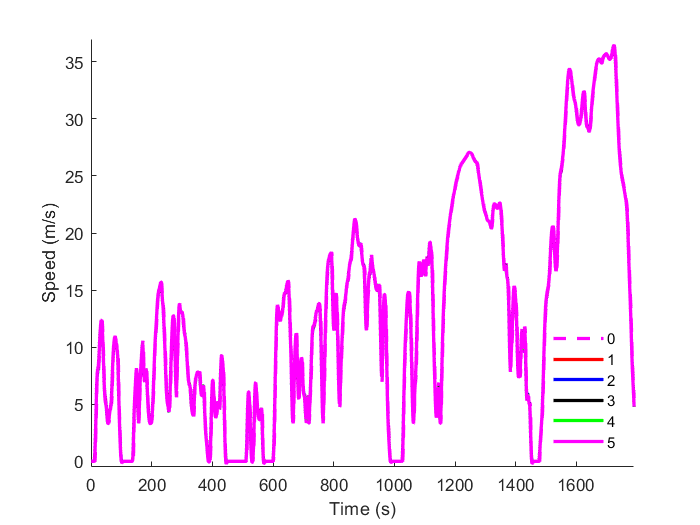

figure;
plot(t,v0,'m--','linewidth',2);
hold on; plot(t, Velocity(:,1),'r','linewidth',2);
plot(t, Velocity(:,2),'b','linewidth',2);
plot(t, Velocity(:,3),'k','linewidth',2);
plot(t, Velocity(:,4),'g','linewidth',2);
plot(t, Velocity(:,5),'m','linewidth',2);
h = legend('0','1','2','3','4','5','Location','SouthEast');
set(h,'box','off'); box off;
xlabel('Time (s)');ylabel('Speed (m/s)');
axis([0 T_plot -0.5 floor(max(max(Velocity))+1)])

### 转矩

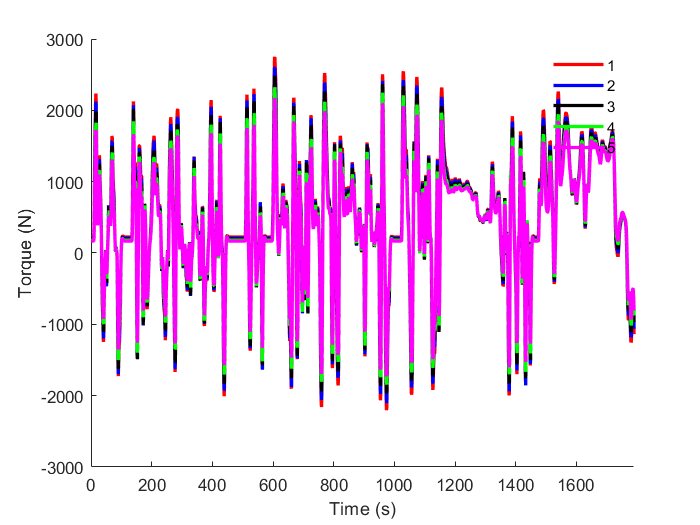

figure;
plot(t, Torque(:,1),'r','linewidth',2);hold on;
plot(t, Torque(:,2),'b','linewidth',2);hold on;
plot(t, Torque(:,3),'k','linewidth',2);hold on;
plot(t, Torque(:,4),'g','linewidth',2);hold on;
plot(t, Torque(:,5),'m','linewidth',2);hold on;
h = legend('1','2','3','4','5');
set(h,'box','off'); box off;
xlabel('Time (s)');ylabel('Torque (N)');
xlim([0 T_plot])

### 加速度

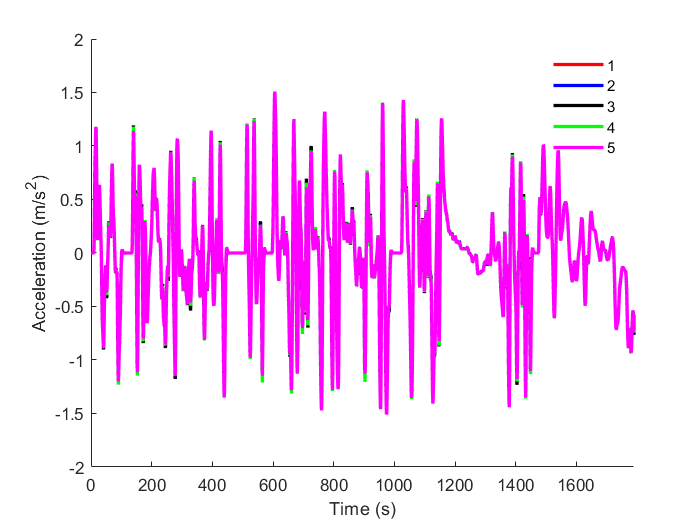

for i = 1:T_plot
    Acc(i,1) = (Eta*Torque(i,1)/R(1) - Ca(1)*Velocity(i,1).^2 - Mass(1)*g*f)/Mass(1);
    Acc(i,2) = (Eta*Torque(i,2)/R(2) - Ca(2)*Velocity(i,2).^2 - Mass(2)*g*f)/Mass(2);
    Acc(i,3) = (Eta*Torque(i,3)/R(3) - Ca(3)*Velocity(i,3).^2 - Mass(3)*g*f)/Mass(3);
    Acc(i,4) = (Eta*Torque(i,4)/R(4) - Ca(4)*Velocity(i,4).^2 - Mass(4)*g*f)/Mass(4);
    Acc(i,5) = (Eta*Torque(i,5)/R(5) - Ca(5)*Velocity(i,5).^2 - Mass(5)*g*f)/Mass(5);
end
figure;
plot(t, Acc(:,1),'r','linewidth',2);hold on;
plot(t, Acc(:,2),'b','linewidth',2);hold on;
plot(t, Acc(:,3),'k','linewidth',2);hold on;
plot(t, Acc(:,4),'g','linewidth',2);hold on;
plot(t, Acc(:,5),'m','linewidth',2);hold on;
h = legend('1','2','3','4','5','Location','NorthEast');
set(h,'box','off'); box off;
xlabel('Time (s)');ylabel('Acceleration (m/s^2)');
xlim([0 T_plot])

### 间距误差

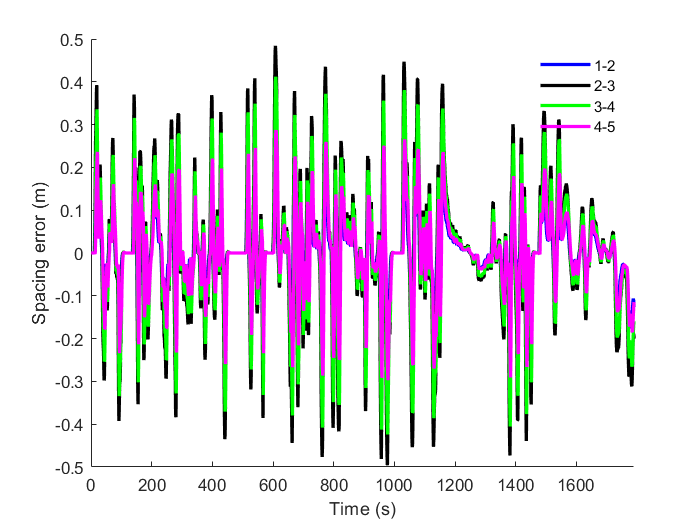

figure;
plot(t, Postion(:,1) - d - Postion(:,2),'b','linewidth',2);hold on;    % 1车与2车误差
plot(t, Postion(:,2) - d - Postion(:,3),'k','linewidth',2);hold on;    % 2车与3车误差
plot(t, Postion(:,3) - d - Postion(:,4),'g','linewidth',2);hold on;    % 3车与4车误差
plot(t, Postion(:,4) - d - Postion(:,5),'m','linewidth',2);hold on;    % 4车与5车误差
h = legend('1-2','2-3','3-4','4-5');
set(h,'box','off'); box off;
xlabel('Time (s)');ylabel('Spacing error (m)');
xlim([0 T_plot])

d12 = Postion(:,1) - d - Postion(:,2);
d23 = Postion(:,2) - d - Postion(:,3);
d34 = Postion(:,3) - d - Postion(:,4);
d45 = Postion(:,4) - d - Postion(:,5);

### 累积误差

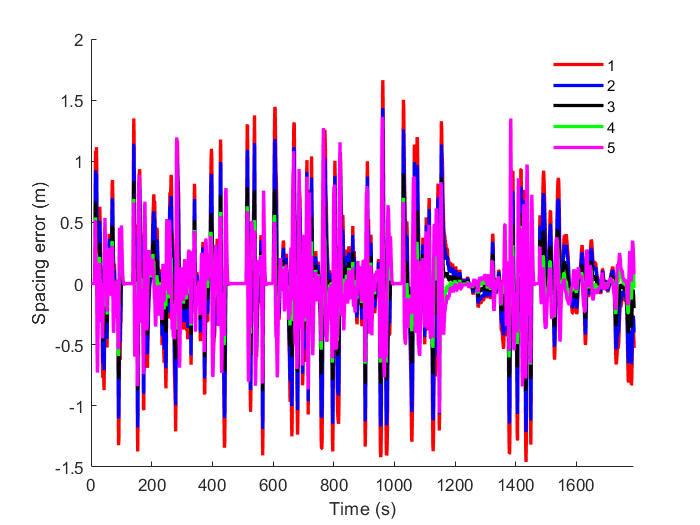

figure;
plot(t, Postion(:,1)- (x0- d),'r','linewidth',2);hold on;
plot(t, Postion(:,2)-(x0- 2*d) ,'b','linewidth',2);hold on;
plot(t, Postion(:,3)-(x0- 3*d),'k','linewidth',2);hold on;
plot(t, Postion(:,4)-(x0- 4*d),'g','linewidth',2);hold on;
plot(t, Postion(:,5)-(x0- 5*d),'m','linewidth',2);hold on;
h = legend('1','2','3','4','5');
set(h,'box','off'); box off;
xlabel('Time (s)');ylabel('Spacing error (m)');
xlim([0 T_plot])

### 状态保存

save('Data/PLF_DMPC_WLTC.mat')